# **How to Use the Solvers?**

**Notes: **More info about the ODEs and the methods are linked in each section.

## **0. Defining Some ODEs**

### 0.1. Simple Harmonic Oscillator Model:

The Simple Harmonic Oscillator is a fundamental model in physics and engineering that describes the behavior of systems undergoing harmonic motion. It can represent various physical systems such as a mass attached to a spring or a pendulum.

The equation of motion for a simple harmonic oscillator is given by:

    
$$\mathbf{m}\frac{{\mathrm{d}}^2 }{\mathrm{d}{\mathbf{t}}^2 }\mathbf{x}+\textrm{kx}=0$$


where:

    - $\mathit{\mathbf{m}}$ is the mass of the object,

    - $\mathit{\mathbf{k}}$ is the spring constant,

    - $\mathit{\mathbf{x}}$ is the displacement of the object from its equilibrium position, and

    - $\mathit{\mathbf{t}}$ is time.

This second-order ordinary differential equation (ODE) governs the motion of the oscillator. It states that the acceleration of the object is directly proportional to its displacement from equilibrium, but in the opposite direction.

To express this equation in terms of a system of first-order ODEs, we introduce the velocity $\(v = \frac{{dx}}{{dt}}\)$. Then, the system becomes:

    
$$\left\lbrace \begin{array}{ll}
\frac{\mathrm{d}}{\mathrm{d}\mathbf{t}}\mathbf{x}=\mathbf{v} & \\
\frac{\mathrm{d}}{\mathrm{d}\mathbf{t}}\mathbf{v}=\frac{-\mathbf{k}}{\mathbf{m}}\mathbf{x} & 
\end{array}\right.$$


These equations form a coupled system that can be solved numerically to understand the motion of the simple harmonic oscillator over time.

% Equation:
%             M*d2x/dt2 = -K*x

% Parameters
M = 1;                              % Mass
K = 1;                              % Spring constant

% Inline ODE Function
f1 = @(t,x) [x(2); -K/M*x(1)];

### 0.2. Logistic Growth Model:

The Logistic growth model is a mathematical model used to describe the population growth of organisms in an environment with limited resources. It assumes that the population growth rate depends not only on the current population size but also on the carrying capacity of the environment.

The model is described by the following ordinary differential equation (ODE):

    
$$\frac{\mathrm{d}}{\mathrm{d}\mathbf{t}}\mathbf{N}=\textrm{rN}\left(1-\frac{\mathbf{N}}{\mathbf{K}}\right)$$


Where:

    - $\mathbf{N}$is the population size at time $\mathit{\mathbf{t}}$.

    - $\mathit{\mathbf{r}}$ is the intrinsic growth rate of the population.

    - $\mathit{\mathbf{K}}$ is the carrying capacity of the environment, representing the maximum sustainable population size.

**More Intuition:**

- When the population size $\mathit{\mathbf{N}}$ is small relative to the carrying capacity $\mathit{\mathbf{K}}$, the term $\(\left(1 - \frac{{N}}{{K}}\right)\)$ is close to 1, resulting in a population growth rate approximately proportional to $\textrm{rN}$. This corresponds to exponential growth.

- As the population size approaches the carrying capacity $\mathit{\mathbf{K}}$, the term$\(\left(1 - \frac{{N}}{{K}}\right)\)$ decreases, causing the growth rate to decrease. This leads to a sigmoidal (S-shaped) growth curve, characteristic of logistic growth.

- At the carrying capacity $\mathit{\mathbf{K}}$, the population growth rate becomes zero, indicating that the environment cannot support further population growth.

The logistic growth model is widely used in ecology, biology, and other fields to understand and predict population dynamics in natural and controlled environments.

% Equation:
%             dx/dt = r*N*(1 - N/K)

% Parameters
r = 0.1;                            % Growth Rate
K = 10;                             % Carrying Capacity

% Inline ODE Function
f2 = @(t,N) r*N*(1 - N/K);

### 0.3. Lotka-Volterra Predator-Prey Model:

The Lotka-Volterra predator-prey model is a mathematical representation of the interaction between two species in an ecosystem, typically a predator and its prey. It consists of two differential equations that describe the population dynamics of both species over time.

The model assumes the following:

    - $\mathit{\mathbf{x}}\left(\mathit{\mathbf{t}}\right)$represents the population of the prey species (e.g., rabbits).

    - $\mathit{\mathbf{y}}\left(\mathit{\mathbf{t}}\right)$ represents the population of the predator species (e.g., foxes).

    - $\alpha$ is the prey birth rate.

    - $\beta$ is the predation rate.

    - $\delta$ is the predator growth rate.

    - $\gamma$ is the predator death rate.

The equations are:

                                    
$$\[
\frac{{\textbf{dx}}}{{\textbf{dt}}} = \alpha \textbf{x} - \beta \textbf{xy}
\]

\[
\frac{{\textbf{dy}}}{{\textbf{dt}}} = \delta \textbf{xy} - \gamma \textbf{y}
\]$$


Here's a simple explanation:

- The first equation describes how the prey population changes over time. The term $\alpha \mathit{\mathbf{x}}$ represents the prey reproduction rate, where more prey are born as the population increases. The term $\beta \mathit{\mathbf{x}}$ represents the predation rate, where prey are consumed by predators, causing the population to decrease

- The second equation describes how the predator population changes over time. The term $\delta \textrm{xy}$ represents the predator growth rate, where more predators are born as they consume prey. The term $\gamma \mathit{\mathbf{y}}$ represents the predator death rate, where predators die off naturally or due to lack of food.

These equations capture the cyclic nature of predator-prey interactions, where changes in one population affect the other population, leading to oscillations in both populations over time.

% Equations:
%           dx/dt =   Alpha*x - Beta*x*y
%           dy/dt = Delta*x*y - Gamma*y

% Parameters
Alpha = 0.1;                                % Prey birth rate
Beta = 0.02;                                % Predation rate
Delta = 0.01;                               % Predator growth rate
Gamma = 0.1;                                % Predator death rate

% Inline ODE Function
f3 = @(t,x) [Alpha*x(1) - Beta*x(1)*x(2); Delta*x(1)*x(2) - Gamma*x(2)];

### 0.4. Van der Pol Oscillator:

The Van der Pol oscillator is a mathematical model that describes the behavior of a nonlinear oscillator with damping. It's commonly used to study phenomena like relaxation oscillations and chaos in various systems.

       
$$\[
\frac{{dx}}{{dt}} = y
\]
\[
\frac{{dy}}{{dt}} = \mu \left(1 - x^2\right)y - x
\]
$$


In these equations:

    - $\mathit{\mathbf{x}}$ represents the position of the oscillator.

    - $\mathit{\mathbf{y}}$ represents the velocity of the oscillator.

    - $\mu$ is a parameter that controls the nonlinearity and damping strength of the oscillator.

The first equation describes the rate of change of position with respect to time, which is simply the velocity $\mathit{\mathbf{y}}$.

The second equation describes the rate of change of velocity with respect to time. It includes a damping term $\mathit{\mathbf{x}}$  and a nonlinear term $\(\mu \left(1 - x^2\right)y\)$, which becomes significant when $\mathit{\mathbf{x}}$  is large, leading to complex behavior such as limit cycles and chaos.

% Equation:
%           dx/dt = y
%           dy/dt = Mu*(1 - x^2)*y - x

% Parameters
Mu = 1;                                 % Parameter

% Inline ODE Function
f4 = @(t,x) [x(2); Mu*(1 - x(1)^2)*x(2) - x(1)];

## **1. Solvings:**

### **1.2. **Harmonic Oscillator Model Simulation using 6th Order Runge-Kutta Method

***Note**: Rememeber to add the directory to the odeRK4 to the matlab path variable.

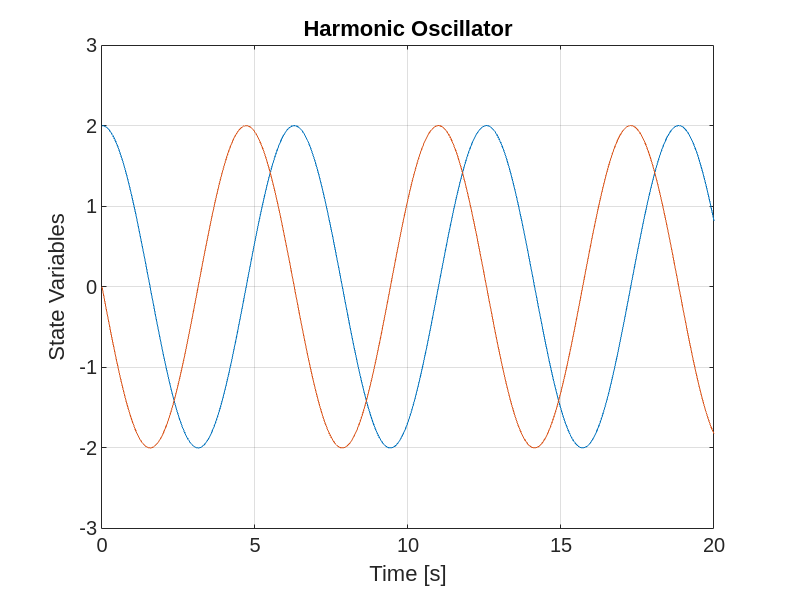

TSpan= [0, 20];    % Time span
Y0= [2; 0];        % Initial condition
h = 0.01;          % Step size
[T, Y] = odeRK4(f1, TSpan, Y0, h);

% Plot results
figure;
plot(T, Y);
xlabel('Time [s]');
ylabel('State Variables');
title('Harmonic Oscillator');
grid on;
axis([0, 20, -3, 3]);

### **1.2. **Logistic Growth Model Simulation using 6th Order Runge-Kutta Butchers Method

***Note**: Rememeber to add the directory to the odeRKB6 to the matlab path variable.

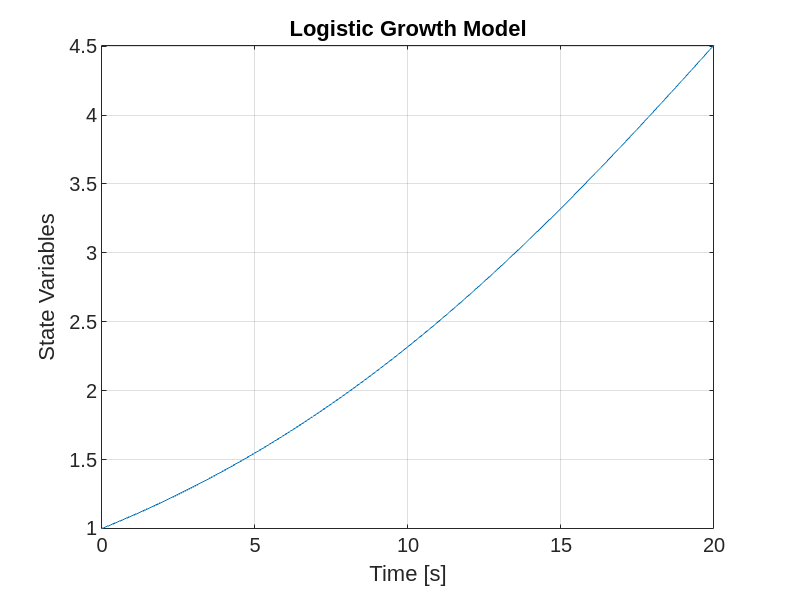

TSpan= [0, 20];    % Time span
Y0= 1;             % Initial condition
h = 0.01;          % Step size
[T, Y] = odeRKB6(f2, TSpan, Y0, h);

% Plot results
figure;
plot(T, Y);
xlabel('Time [s]');
ylabel('State Variables');
title('Logistic Growth Model');
grid on;
axis tight;

### **1.3. **Lotka-Volterra Predator-Prey Model Simulation using 7th Order Runge-Kutta Method

***Note**: Rememeber to add the directory to the odeRK7 to the matlab path variable.

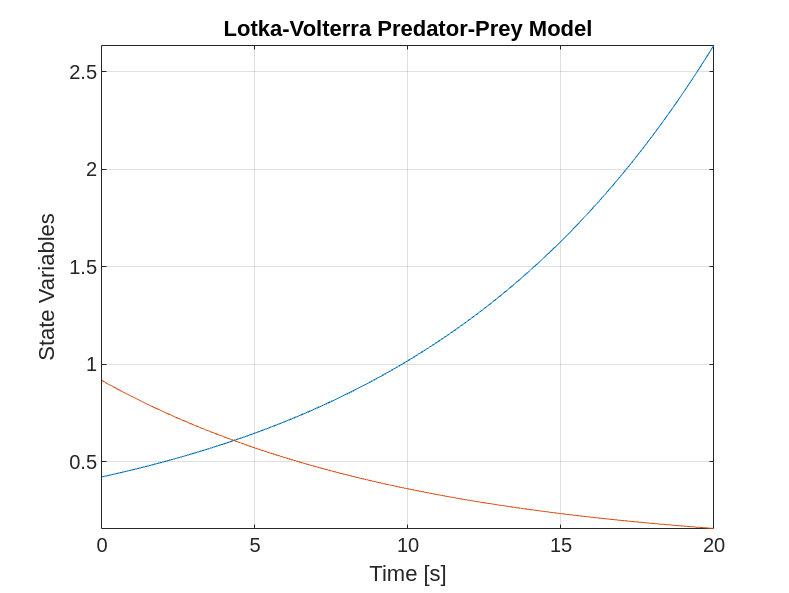

TSpan= [0, 20];    % Time span
Y0= rand(2, 1);        % Initial condition
h = 0.01;          % Step size
[T, Y] = odeRK7(f3, TSpan, Y0, h);

% Plot results
figure;
plot(T, Y);
xlabel('Time [s]');
ylabel('State Variables');
title('Lotka-Volterra Predator-Prey Model');
grid on;
axis tight;

### **1.4 **Van der Pol Oscillator Simulation using 10th Order Runge-Kutta Zhangs Method

***Note**: Rememeber to add the directory to the odeRKZ10 to the matlab path variable.

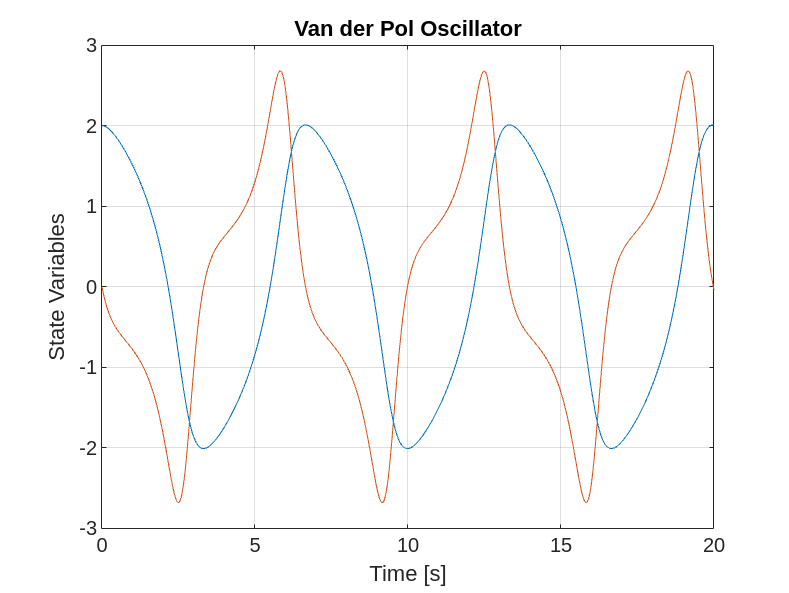

TSpan= [0, 20];    % Time span
Y0= [2; 0];        % Initial condition
h = 0.01;          % Step size
[T, Y] = odeRK4(f4, TSpan, Y0, h);

% Plot results
figure;
plot(T, Y);
xlabel('Time [s]');
ylabel('State Variables');
title('Van der Pol Oscillator');
grid on;
axis([0, 20, -3, 3]);